# **Lidar-based localization and pcd map reconstruction**

## A) Exploring and visualizing data from Bag file.

%___Create a bag reader___%
bagPath = '/home/hazem/Downloads/micropolis_bag_files/';
fullFilePath = fullfile(bagPath, "micropolis_bag_07.mcap");
bagRead = ros2bagreader(fullFilePath);

%___Extract bag file info___%
bagInfo = ros2("bag","info", fullFilePath)

bagInfo = struct with fields:
                 Path: '/home/hazem/Downloads/micropolis_bag_files/micropolis_bag_07.mcap'
      FileInformation: "micropolis_bag_07.mcap"
              Version: '9'
            StorageId: 'mcap'
             Duration: 50.9304
                Start: [1×1 struct]
                  End: [1×1 struct]
                 Size: 2638272668
             Messages: 9415
                Types: [3×1 struct]
               Topics: [3×1 struct]
    CompressionFormat: 'none'
      CompressionMode: 'none'


%___Create a variables to hold different messages___%
ENUSel = select(bagRead, "Topic", "/fixposition/odometry_enu");
LLHSel = select(bagRead, "Topic", "/fixposition/odometry_llh");
PCDSel = select(bagRead, "Topic", "/iv_points_fusion");

%___ENU Ground-truth data___%
ENUMsgs = readMessages(ENUSel);
%___Access a single cell from the cell array___%
ENUMsgs{1}

ans = struct with fields:
       MessageType: 'nav_msgs/Odometry'
            header: [1×1 struct]
    child_frame_id: 'FP_POI'
              pose: [1×1 struct]
             twist: [1×1 struct]


%___Extracting ground-truth data and plotting trajectory in ENU coordinates___%
GT_X = zeros(length(ENUMsgs),1);
GT_Y = zeros(length(ENUMsgs),1);
GT_Z = zeros(length(ENUMsgs),1);
for i = 1:length(ENUMsgs)
    GT_X(i) = ENUMsgs{i}.pose.pose.position.x;
    GT_Y(i) = ENUMsgs{i}.pose.pose.position.y;
    GT_Z(i) = ENUMsgs{i}.pose.pose.position.z;
end

dX = diff(GT_X);
dY = diff(GT_Y);
dZ = diff(GT_Z);
dP = sqrt(dX.^2 + dY.^2 + dZ.^2);
totalDist = sum(dP);
fprintf('Total flight distance : %.3f m\n', totalDist)

Total flight distance : 116.128 m


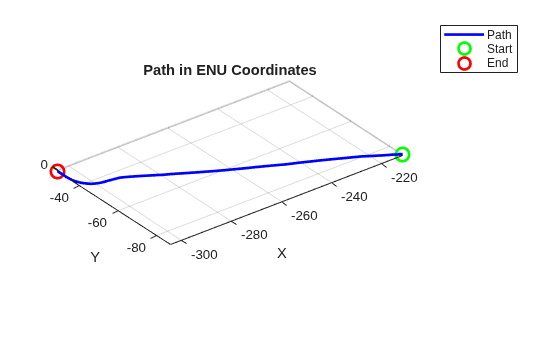

figure
plot3(GT_X, GT_Y, GT_Z, 'b', 'LineWidth', 2)
hold on
plot3(GT_X(1), GT_Y(1), GT_Z(1), 'go', 'LineWidth', 2, 'MarkerSize', 10)
plot3(GT_X(end), GT_Y(end), GT_Z(end), 'ro', 'LineWidth', 2, 'MarkerSize', 10)
grid on
axis equal
title(sprintf('Path in ENU Coordinates'))
legend('Path', 'Start', 'End')
xlabel("X")
ylabel("Y")
zlabel("Z")

LLHMsgs = readMessages(LLHSel);
%___Access a single cell from the cell array___%
LLHMsgs{1}

ans = struct with fields:
                       MessageType: 'sensor_msgs/NavSatFix'
                            header: [1×1 struct]
                            status: [1×1 struct]
                          latitude: 25.2326
                         longitude: 55.3685
                          altitude: -17.6478
               position_covariance: [9×1 double]
           COVARIANCE_TYPE_UNKNOWN: 0
      COVARIANCE_TYPE_APPROXIMATED: 1
    COVARIANCE_TYPE_DIAGONAL_KNOWN: 2
             COVARIANCE_TYPE_KNOWN: 3
          position_covariance_type: 3


%___Extracting ground-truth data and plotting trajectory in ENU coordinates___%
GT_Lat = zeros(length(LLHMsgs),1);
GT_Lon = zeros(length(LLHMsgs),1);
for i = 1:length(LLHMsgs)
    GT_Lat(i) = LLHMsgs{i}.latitude;
    GT_Lon(i) = LLHMsgs{i}.longitude;
end

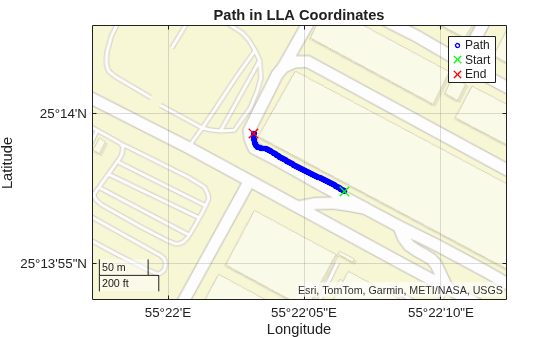

%___Plotting Ground-truth LLA data in a global map___%
figure
geoplot(GT_Lat, GT_Lon, 'bo', 'LineWidth', 1, 'MarkerSize', 3)
geobasemap streets
hold on
geoplot(GT_Lat(1), GT_Lon(1),'gx', 'LineWidth', 1, 'MarkerSize', 10)
geoplot(GT_Lat(end), GT_Lon(end), 'rx', 'LineWidth', 1, 'MarkerSize', 10)
grid on
title(sprintf('Path in LLA Coordinates'))
legend('Path', 'Start', 'End')
margin = 0.001;
geolimits([min(GT_Lat)-margin max(GT_Lat)+margin], ...
    [min(GT_Lon)-margin max(GT_Lon)+margin])

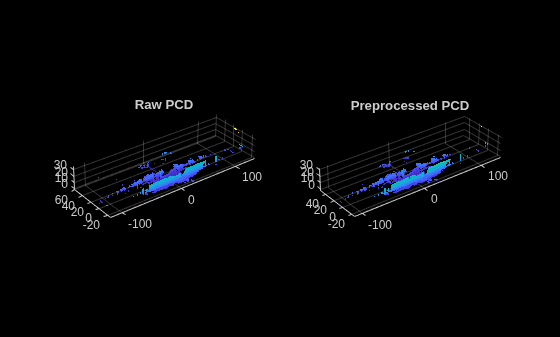

%___Access a single cell from the cell array___%
PCDCurr = readMessages(PCDSel,10);
PCDCurr = pointCloud(rosReadXYZ(PCDCurr{1}));
%__Now preprocessing the ptc data before registration___%
PTCloud = removeInvalidPoints(PCDCurr);
PTCloud = pcdownsample(PTCloud, "gridAverage", 0.2);
PTCloud = pcdenoise(PTCloud, "PreserveStructure",true, "Threshold", 2.0);
figure
subplot(1,2,1)
pcshow(PCDCurr)
title("Raw PCD")
subplot(1,2,2)
pcshow(PTCloud)
title("Preprocessed PCD")

disp(['Numbers of points before preprocessing: ', num2str(PCDCurr.Count), ' | and after preprocessing: ', num2str(PTCloud.Count)])

Numbers of points before preprocessing: 346136 | and after preprocessing: 61503


## B) Registering point cloud frames and obtaining Poses and Accumulating 3D world point cloud map. 

%__Helper functions__%
function ptOut = localPreprocess(rawXYZ, voxel_leaf_size, min_range, max_range, max_points)
%1-Voxel downsample
%2-Radial range filter [min_range, max_range]
%3-Random cap to max_points (uniform keep_ratio, matches rand()/RAND_MAX < keep_ratio)

    ptIn = pointCloud(rawXYZ);
    ptIn = removeInvalidPoints(ptIn);

    %Voxel-downsample
    ptVox = pcdownsample(ptIn, "gridAverage", voxel_leaf_size);

    if ptVox.Count == 0
        ptOut = ptVox;
        return
    end

    %Range filter (radial distance from sensor origin)
    xyz = ptVox.Location;
    r2  = sum(xyz.^2, 2);
    keepIdx = (r2 >= min_range^2) & (r2 <= max_range^2);
    xyzRange = xyz(keepIdx, :);

    if isempty(xyzRange)
        ptOut = pointCloud(zeros(0,3));
        return
    end

    %Random point cap (uniform random keep, same scheme as rand() < keep_ratio)
    nPts = size(xyzRange,1);
    if nPts > max_points
        keep_ratio = max_points / nPts;
        mask = rand(nPts,1) < keep_ratio;
        xyzCapped = xyzRange(mask, :);
        % Mirror the C++ early-break: trim if the random draw overshoots
        if size(xyzCapped,1) > max_points
            xyzCapped = xyzCapped(1:max_points, :);
        end
    else
        xyzCapped = xyzRange;
    end

    ptOut = pointCloud(xyzCapped);
end

function [bestTform, bestFitness, converged, bestName] = multiHypothesisRegister( ...
    source, target, hypotheses, resolution, epsilon, maxIter, fitnessThreshold, frame_idx, stage_label)
    %Tries each candidate initial guess against `target`, keeps whichever converges (hasConverged-equivalent: didn't throw, fitness < threshold)
    bestTform   = rigidtform3d(eye(4));
    bestFitness = NaN;
    converged   = false;
    bestName    = 'none';

    for k = 1:numel(hypotheses)
        initTform = rigidtform3d(hypotheses(k).guess);
        try
            [tform, ~, rmse] = pcregisterndt(source, target, resolution, ...
                'InitialTransform', initTform, ...
                'Tolerance', [epsilon, epsilon], ...
                'MaxIterations', maxIter);
        catch ME
            fprintf('Frame %d: pcregisterndt threw on %s hypothesis "%s" — %s\n', ...
                frame_idx, stage_label, hypotheses(k).name, ME.message);
            continue
        end

        if isnan(rmse) || rmse >= fitnessThreshold
            continue 
        end

        if ~converged || rmse < bestFitness
            bestTform   = tform;
            bestFitness = rmse;
            converged   = true;
            bestName    = hypotheses(k).name;
        end
    end

    if ~converged
        bestFitness = NaN;
    end
end

function T_scaled = se3LogScale(T, alpha)
%Scales a rigid-body transform T by factor alpha

    R = T(1:3,1:3);
    t = T(1:3,4);

    axang = rotm2axang(R);
    if abs(axang(4)) < 1e-9
        R_scaled = eye(3);
    else
        axang(4) = axang(4) * alpha;
        R_scaled = axang2rotm(axang);
    end

    T_scaled = eye(4);
    T_scaled(1:3,1:3) = R_scaled;
    T_scaled(1:3,4)   = t * alpha;
end

function map_out = accumulateMapLocal(map_in, cloud_in_map, frame_count, revoxel_every, map_leaf)
%Mirrors accumulateMap(): append, then periodically re-voxelise the WHOLE accumulated map.

    if map_in.Count == 0
        merged = cloud_in_map;
    else
        merged = pointCloud([map_in.Location; cloud_in_map.Location]);
    end

    if mod(frame_count, revoxel_every) == 0 && merged.Count > 0
        map_out = pcdownsample(merged, "gridAverage", map_leaf);
        fprintf('Map re-voxelised at frame %d: %d points\n', frame_count, map_out.Count);
    else
        map_out = merged;
    end
end


%__Parameters__% 
voxel_leaf_size       = 0.1;     %cloudCallback: vg.setLeafSize(voxel_leaf_size_)
map_voxel_leaf_size   = 0.1;     %accumulateMap: vg.setLeafSize(map_voxel_leaf_size_)
max_scan_range        = 40.0;    %range filter upper bound (m)
map_min_points        = 150000;  %switch to scan-to-map once map this dense
map_revoxel_every      = 50;     %re-voxelise accumulated map every N frames

ndt_resolution         = 0.5;    %pcregisterndt 'Resolution' below replicates this
ndt_epsilon            = 1e-4;   %transformation epsilon -> 'Tolerance'
ndt_max_iter           = 60;     %'MaxIterations'
ndt_fitness_threshold  = 0.5;    %accept threshold, scan-to-map
ndt_fitness_threshold_fallback = ndt_fitness_threshold * 2.0; % scan-to-scan fallback threshold (1.0)

N = PCDSel.NumMessages;

lidarT = zeros(N,3);
lidarR = zeros(3,3,N);
fitnessLog = nan(N,1);
acceptedLog = false(N,1);

T_map_lidar = eye(4); 
T_delta     = eye(4); 

map_cloud   = pointCloud(zeros(0,3)); 
prev_cloud  = pointCloud(zeros(0,3)); 

consecutive_failures = 0;
roi = [-max_scan_range max_scan_range -max_scan_range max_scan_range -inf inf];

%__Main loop__%
for i = 1:N
    msgCurr  = readMessages(PCDSel, i);
    rawXYZ   = rosReadXYZ(msgCurr{1});

    cloud_filtered = preprocessScan(rawXYZ);

    if cloud_filtered.Count == 0
        warning('Frame %d: empty filtered cloud — skipping.', i);
        continue
    end

    %__Bootstrap: first scan seeds the map at identity__%
    if i == 1
        prev_cloud  = cloud_filtered;
        T_map_lidar = eye(4);
        T_delta     = eye(4);

        %Accumulate first scan directly
        map_cloud = accumulateMapLocal(map_cloud, cloud_filtered, 1, ...
                        map_revoxel_every, map_voxel_leaf_size);

        lidarT(1,:)   = T_map_lidar(1:3,4)';
        lidarR(:,:,1) = T_map_lidar(1:3,1:3);
        acceptedLog(1) = true;
        fitnessLog(1)  = 0;

        fprintf('Bootstrap complete — first scan added (%d pts).\n', cloud_filtered.Count);
        continue
    end

    %__Multi-hypothesis initial guesses__%

    T_delta_half = se3LogScale(T_delta, 0.5);  % dampened extrapolation

    hypotheses = struct( ...
        'name',  {'extrapolated', 'no-motion', 'half-extrapolated'}, ...
        'guess', {T_map_lidar * T_delta, T_map_lidar, T_map_lidar * T_delta_half});

    %__NDT scan-to-map (if map dense enough) else scan-to-prev__%
    use_map = (map_cloud.Count >= map_min_points);
    if use_map
        target_cloud = map_cloud;
    else
        target_cloud = prev_cloud;
    end

    [tform, fitness, converged, used_hyp] = multiHypothesisRegister( ...
        cloud_filtered, target_cloud, hypotheses, ...
        ndt_resolution, ndt_epsilon, ndt_max_iter, ndt_fitness_threshold, ...
        i, 'scan-to-map');

    %__Fallback to scan-to-scan if ALL scan-to-map hypotheses failed__%
    if ~converged && use_map
        fprintf('Frame %d: all scan-to-map hypotheses failed — retrying scan-to-scan\n', i);

        [tform, fitness, converged, used_hyp] = multiHypothesisRegister( ...
            cloud_filtered, prev_cloud, hypotheses, ...
            ndt_resolution, ndt_epsilon, ndt_max_iter, ndt_fitness_threshold_fallback, ...
            i, 'scan-to-scan');
    end

    %__Accept or reject__%
    if converged
        T_new = tform.A;             

        %Motion prior is derived from whichever hypothesis actually won.
        T_delta     = T_map_lidar \ T_new;
        T_map_lidar = T_new;

        consecutive_failures = 0;

        fprintf('Frame %4d  fitness=%.4f  hyp=%-18s pos=[%.2f, %.2f, %.2f]\n', ...
            i, fitness, used_hyp, T_map_lidar(1,4), T_map_lidar(2,4), T_map_lidar(3,4));
    else
        consecutive_failures = consecutive_failures + 1;
        if isnan(fitness)
            fprintf('Frame %d: NDT threw on every hypothesis/target (consecutive failures=%d) — holding last pose\n', ...
                i, consecutive_failures);
        else
            fprintf('Frame %d: NDT diverged on every hypothesis (best fitness=%.4f, consecutive failures=%d) — holding last pose\n', ...
                i, fitness, consecutive_failures);
        end
    end

    lidarT(i,:)    = T_map_lidar(1:3,4)';
    lidarR(:,:,i)  = T_map_lidar(1:3,1:3);
    fitnessLog(i)  = fitness;
    acceptedLog(i) = converged;

    %__Accumulate FULL filtered scan transformed by current pose__%
    transformedXYZ = (T_map_lidar(1:3,1:3) * cloud_filtered.Location' + T_map_lidar(1:3,4))';
    cloud_in_map   = pointCloud(transformedXYZ);

    map_cloud = accumulateMapLocal(map_cloud, cloud_in_map, i, ...
                    map_revoxel_every, map_voxel_leaf_size);

    prev_cloud = cloud_filtered;
end

Frame  401  fitness=0.1433  hyp=half-extrapolated  pos=[106.69, 2.99, -2.19]
Frame  402  fitness=0.1192  hyp=half-extrapolated  pos=[106.78, 2.84, -2.19]
Frame  403  fitness=0.1542  hyp=extrapolated       pos=[107.14, 2.26, -2.19]
Frame  404  fitness=0.1119  hyp=no-motion          pos=[107.22, 2.11, -2.19]
Frame  405  fitness=0.1242  hyp=no-motion          pos=[107.49, 1.69, -2.19]
Frame  406  fitness=0.1131  hyp=no-motion          pos=[107.58, 1.55, -2.19]
Frame  407  fitness=0.1162  hyp=no-motion          pos=[107.83, 1.14, -2.19]
Frame  408  fitness=0.1059  hyp=extrapolated       pos=[107.91, 1.00, -2.19]
Frame  409  fitness=0.1186  hyp=extrapolated       pos=[108.17, 0.62, -2.19]
Frame  410  fitness=0.0942  hyp=half-extrapolated  pos=[108.24, 0.49, -2.19]
Frame  411  fitness=0.0974  hyp=no-motion          pos=[108.32, 0.36, -2.19]
Frame  412  fitness=0.1025  hyp=half-extrapolated  pos=[108.48, 0.11, -2.18]
Frame  413  fitness=0.1040  hyp=extrapolated       pos=[108.56, -0.02, -2.19

Map re-voxelised at frame 450: 1360548 points


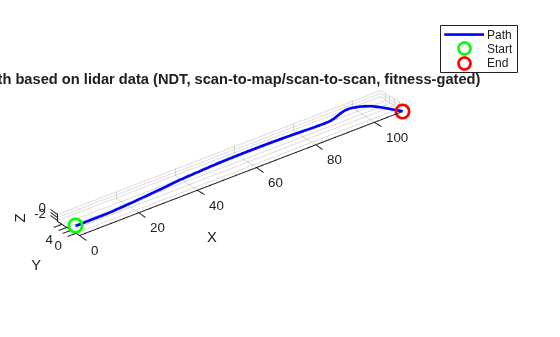

%__Plot resulting trajectory__%
figure
plot3(lidarT(:,1), lidarT(:,2), lidarT(:,3), 'b', 'LineWidth', 2)
hold on
plot3(lidarT(1,1), lidarT(1,2), lidarT(1,3), 'go', 'LineWidth', 2, 'MarkerSize', 10)
plot3(lidarT(end,1), lidarT(end,2), lidarT(end,3), 'ro', 'LineWidth', 2, 'MarkerSize', 10)
grid on
axis equal
title('Path based on lidar data (NDT, scan-to-map/scan-to-scan, fitness-gated)')
legend('Path', 'Start', 'End')
xlabel('X'); ylabel('Y'); zlabel('Z')

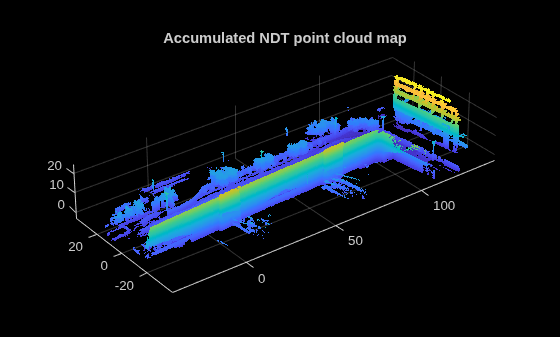

figure
pcshow(map_cloud)
title('Accumulated NDT point cloud map')

fprintf('Frames accepted: %d / %d  (%.1f%%)\n', sum(acceptedLog), N, 100*sum(acceptedLog)/N);

Frames accepted: 450 / 450  (100.0%)


## C) Comparing results with ENU data as ground-truth data

%___Extracting initial Tgv___%
lidarTf = zeros(PCDSel.NumMessages,3);
lidarRf = zeros(3,3,PCDSel.NumMessages);

%Initial translation
lidarTf(1,:) = [GT_X(1), GT_Y(1), GT_Z(1)]';
Tgvf = [1,0,0,GT_X(1); 0,1,0,GT_Y(1); 0,0,1,GT_Z(1); 0,0,0,1];

%Initial Rotation
quatf = [ENUMsgs{1}.pose.pose.orientation.w, ENUMsgs{1}.pose.pose.orientation.x, ENUMsgs{1}.pose.pose.orientation.y, ENUMsgs{1}.pose.pose.orientation.z];
Rinitialf = quat2rotm(quatf);
lidarRf(:,:,1) = Rinitialf;
Tgvf(1:3,1:3) = Rinitialf;
Tgvf %To display initial transformation

Tgvf =    -0.9146   -0.4041    0.0155 -211.5508
    0.4044   -0.9143    0.0211  -87.1346
    0.0056    0.0255    0.9997    0.1857
         0         0         0    1.0000


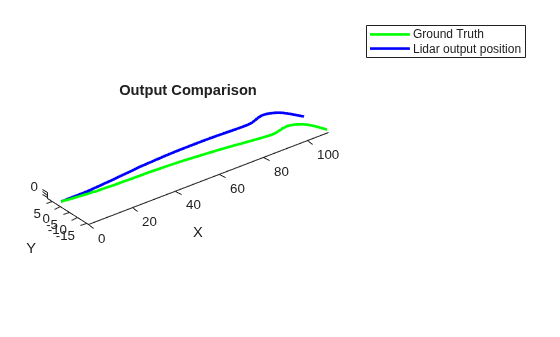

r = round(linspace(1,length(GT_X), length(lidarT)));
GT_X_Reduced = GT_X(r);
GT_Y_Reduced = GT_Y(r);
GT_Z_Reduced = GT_Z(r);
%Referencing ENU ground truth points to first frame origin.
GT_Reduced = ([GT_X_Reduced, GT_Y_Reduced, GT_Z_Reduced] -Tgvf(1:3,4)') * Tgvf(1:3,1:3);

figure;
plot3(GT_Reduced(:,1), GT_Reduced(:,2), GT_Reduced(:,3), 'g', 'LineWidth', 2)
hold on
plot3(lidarT(:,1), lidarT(:,2), lidarT(:,3), 'b', 'LineWidth', 2)
axis equal
title(sprintf('Output Comparison'))
legend('Ground Truth', 'Lidar output position')
xlabel("X")
ylabel("Y")
zlabel("Z")

posDiff = vecnorm(lidarT - [GT_Reduced(:,1) GT_Reduced(:,2) GT_Reduced(:,3)], 2,2);
fprintf('Max position difference %.1f',max(posDiff));